# parameters setting

clc; clear all;
epsilon = 0.0001; % probabilità di fuori servizio
sigma_2 = 3.025088644544423e-19 + 2.580067726249549e-22

sigma_2 = 3.0277e-19

n_sample = 10000;
%inserire sigma_n

% da diseq
delta_0 = 2*sigma_2*(erfinv(1-epsilon))^2* 10e-5 %

delta_0 = 4.5829e-22

delta_n = ((2*sigma_2*(erfinv(1-epsilon))^2)* 10e-5 + delta_0) %

delta_n = 9.1658e-22


eps_space = linspace(0,1, 1000000); 


## LED samples estimation

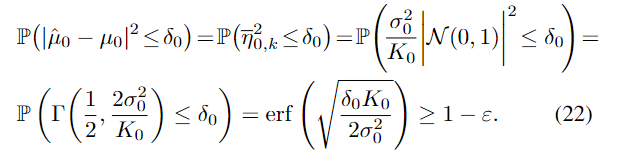

% come varia K_0 al variare di epsilon
figure();
K_0_var = (2/delta_0) .*sigma_2 *(erfinv(1-eps_space)).^2

K_0_var = 	1.0e+04 *

       Inf    1.5808    1.4927    1.4413    1.4049    1.3766    1.3535    1.3341    1.3172    1.3023    1.2890    1.2770    1.2660    1.2559    1.2466    1.2379    1.2298    1.2221    1.2149    1.2081    1.2017    1.1955    1.1897    1.1841    1.1787    1.1736    1.1687    1.1639    1.1594    1.1550    1.1507    1.1466    1.1426    1.1387    1.1350    1.1314    1.1278    1.1244    1.1210    1.1178    1.1146    1.1115    1.1085    1.1055    1.1027    1.0998    1.0971    1.0944    1.0918    1.0892


%plot(eps_space,K_0_var)

% fisso epsilon ed ottengo K_0
K_0 = (2/delta_0) .* sigma_2 * (erfinv(1-epsilon)).^2

K_0 = 10000


% calcolare cdf
y_montecarlo  = ((randn(1,n_sample)).^2).*(sigma_2/K_0)

y_montecarlo = 	1.0e+-21 *

    0.0010    0.0061    0.0052    0.0802    0.0001    0.0197    0.0187    0.0246    0.0252    0.0674    0.0010    0.0145    0.0132    0.0021    0.0062    0.0008    0.0001    0.0238    0.0001    0.0136    0.0216    0.0051    0.0095    0.0006    0.0328    0.0038    0.0122    0.0372    0.0767    0.1173    0.0224    0.0024    0.0025    0.0253    0.0798    0.0001    0.0089    0.0066    0.0437    0.0008    0.0433    0.0362    0.0080    0.0161    0.0011    0.0047    0.0375    0.0000    0.0031    0.0024


ecdf(y_montecarlo);

%ylim([0 1.8e-8])


delta_axis = linspace(0,max(y_montecarlo), 1000000); 
%delta_axis = linspace(0,2*sigma_2*(erfinv(1-epsilon))^2 , 1000000);

y_exact = erf(sqrt(((delta_axis * K_0)/(2*sigma_2))))

y_exact =          0    0.0033    0.0047    0.0057    0.0066    0.0074    0.0081    0.0088    0.0094    0.0099    0.0105    0.0110    0.0115    0.0120    0.0124    0.0128    0.0133    0.0137    0.0141    0.0145    0.0148    0.0152    0.0156    0.0159    0.0162    0.0166    0.0169    0.0172    0.0175    0.0179    0.0182    0.0185    0.0188    0.0190    0.0193    0.0196    0.0199    0.0202    0.0204    0.0207    0.0210    0.0212    0.0215    0.0217    0.0220    0.0222    0.0225    0.0227    0.0230    0.0232


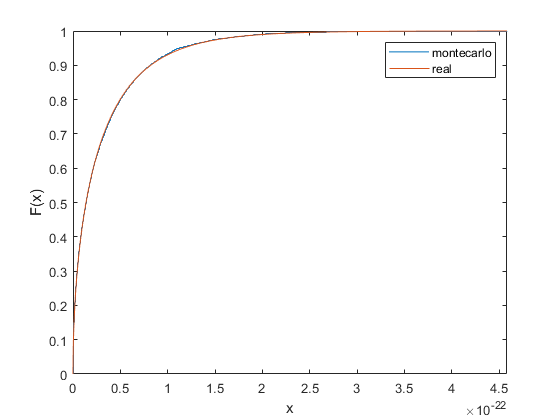

hold on;
plot(delta_axis, y_exact);


xlim([0 2*sigma_2*(erfinv(1-epsilon))^2])
xlim([0 delta_0])

legend('montecarlo', 'real');

## IMR samples estimation

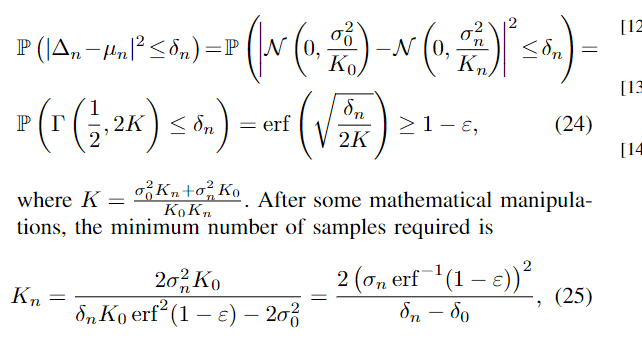

% come varia K_0 al variare di epsilon
figure();
K_n_var = (2/(delta_n - delta_0)) .* sigma_2* (erfinv(1-eps_space)).^2

K_n_var = 	1.0e+04 *

       Inf    1.5808    1.4927    1.4413    1.4049    1.3766    1.3535    1.3341    1.3172    1.3023    1.2890    1.2770    1.2660    1.2559    1.2466    1.2379    1.2298    1.2221    1.2149    1.2081    1.2017    1.1955    1.1897    1.1841    1.1787    1.1736    1.1687    1.1639    1.1594    1.1550    1.1507    1.1466    1.1426    1.1387    1.1350    1.1314    1.1278    1.1244    1.1210    1.1178    1.1146    1.1115    1.1085    1.1055    1.1027    1.0998    1.0971    1.0944    1.0918    1.0892


%plot(eps_space,K_n_var)

% fisso epsilon ed ottengo K_n
K_n = (2/(delta_n - delta_0)) * sigma_2 * (erfinv(1-epsilon))^2

K_n = 10000


K = (sigma_2*K_n + sigma_2*K_0)/(K_0*K_n);
% calcolare cdf
y_montecarlo = (((randn(1,n_sample))).^2) *K

y_montecarlo = 	1.0e+-20 *

    0.0034    0.0121    0.0045    0.0024    0.0176    0.0001    0.0017    0.0396    0.0000    0.0009    0.0004    0.0100    0.0156    0.0252    0.0004    0.0037    0.0043    0.0010    0.0157    0.0204    0.0003    0.0008    0.0095    0.0011    0.0033    0.0473    0.0028    0.0041    0.0055    0.0001    0.0032    0.0135    0.0024    0.0027    0.0000    0.0224    0.0068    0.0018    0.0027    0.0031    0.0003    0.0005    0.0048    0.0244    0.0011    0.0218    0.0039    0.0068    0.0232    0.0003


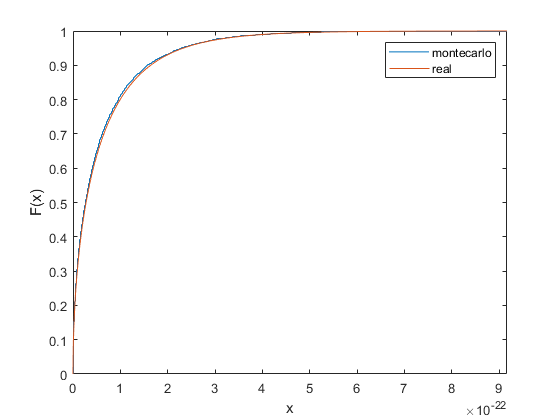

%y_montecarlo  = ((randn(1,n_sample)).^2).*(sigma_2/K_n)

ecdf(y_montecarlo);

%delta_axis = linspace(0,2.5*10e-20, 1000000); 
delta_axis = linspace(0,delta_n, 1000000); 
%delta_axis = linspace(0,max(y_montecarlo), 1000000); 


y_exact = erf(sqrt(((delta_axis)/(2*K))));

hold on;
plot(delta_axis, y_exact);
xlim([0 delta_n])
legend('montecarlo', 'real');